# Figure 3 - Illustrate the main data sets

To measure lip and tongue fluorescence we needed to remove any reflected light from the light source.  These were always below 475nm, so added a 475 nm long pass to the system.  This blocked the reflected light, but allowed fluorescent light to pass. For more explanation, see Figure 1.

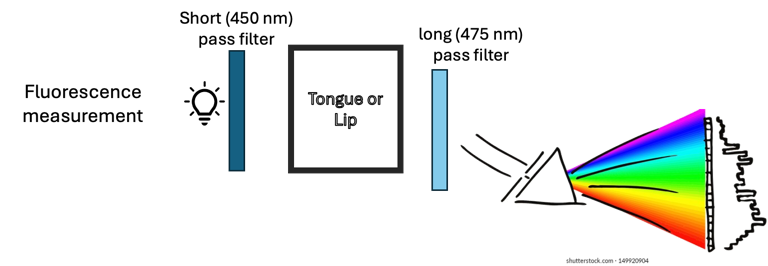

**Caption:** The six panels show the different measurement conditions.  The three columns show data acquired with each of three excitation lights (405 nm, 415 nm, 450nm).  The two rows show data acquired from the lip (top) and the tongue (bottom). The four curves in each panel show data from four different subjects, all measured with the same excitation light.  The curves are all normalized to match at 580 nm.  

Observations for the text:  

- The lip data across subjects are very similar from 500-700 nm.  (We will merge the 405 and 415 nm excitations soon.)

- In that regime we see small modulations at the oxyhemoglobin absorption bands of 540nm and 580nm

- The tongue data are very similar in the 500-600nm

- There are also small dips at the oxyhemoglobin bands, but they are harder to see than in the lip data.

- The tongue data vary between 600-700nm because of porphyrins and chlorophyll 

## Initialize ISET

ieInit;
waves = 500:5:700;
symbols = {'kx-','k*-','k^-','ko-'};
fise_plotDefaults;

% Not normalized.
nWave = 520;  % 580 
yScale = 'linear';
T = oeDatabaseCreate;

## Lip 

### 405 (980 mA)

lipFiles405 = ieTableGet(T,'ewave',405,'substrate','lip','elevel',980,'return','files');
data = oeReadFiles(lipFiles405,'waves',waves,'normalized wave',nWave);

ieFigure;
for ii= 1:numel(lipFiles405)
    % plot(waves,data(:,ii),symbols{ii}); hold on; 
    hA = plot(waves,data(:,ii),'b-'); hold on;
    set(gca,'yscale',yScale);
end
grid on;
xlabel('Wavelength (nm)')
if isempty(nWave), ylabel('Energy (watts/sr/nm/m^2)');
else, ylabel(sprintf('Normalized (re: %d nm)',nWave));
end
% title('Lip (405 ex)');
% legend({'J','Z','B','D'});

### 415 (910 mA)

lipFiles415 = ieTableGet(T,'ewave',415,'substrate','lip','elevel',910);

% Collected on the same day as above.
selected = [11,12,13,14];
lipFiles415 = lipFiles415(selected);
data = oeReadFiles(lipFiles415,'waves',waves,'normalized wave',nWave);

% ieFigure;
for ii= 1:numel(lipFiles415)
    % plot(waves,data(:,ii),symbols{ii}); hold on; 
    hB = plot(waves,data(:,ii),'g-'); hold on; 
    set(gca,'yscale',yScale);
end
grid on;
xlabel('Wavelength (nm)')
if isempty(nWave), ylabel('Energy (watts/sr/nm/m^2)');
else, ylabel(sprintf('Normalized (re: %d nm)',nWave));
end
% title('Lip (415 ex)');
% legend({'J','Z','B','D'});

### 450 (870 mA)

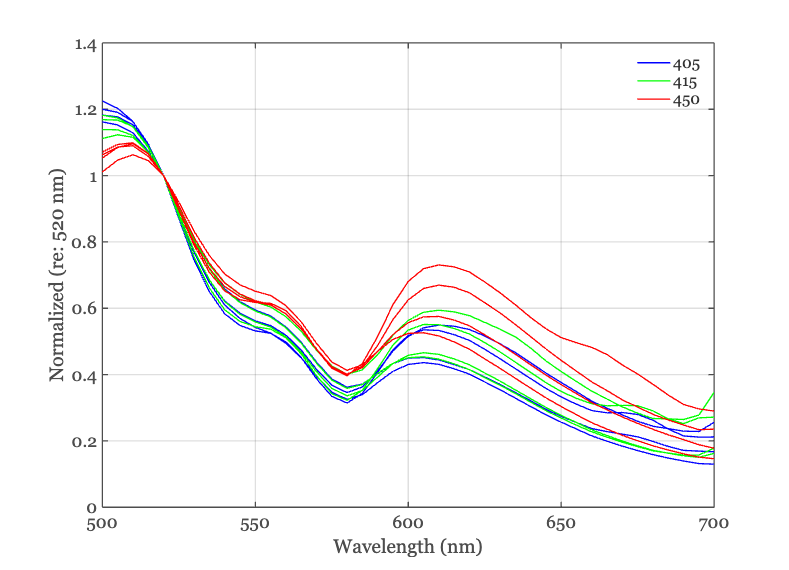

lipFiles450 = ieTableGet(T,'ewave',450,'substrate','lip','elevel',870,'return','files');

data = oeReadFiles(lipFiles450,'waves',waves,'normalized wave',nWave);

% ieFigure;
hold on;
for ii= 1:numel(lipFiles450)
    % plot(waves,data(:,ii),symbols{ii}); hold on; 
    hC = plot(waves,data(:,ii),'r-'); hold on; 
    set(gca,'yscale',yScale);
end
grid on;
xlabel('Wavelength (nm)')
if isempty(nWave), ylabel('Energy (watts/sr/nm/m^2)');
else, ylabel(sprintf('Normalized (re: %d nm)',nWave));
end
% title('Lip (450 ex)');
% legend({'J','Z','B','D'});
legend([hA,hB,hC],{'405','415','450'});
exportgraphics(gcf,'CompareLights-lip.png','Resolution',150);

## Tongue excitations

### 405 (980 mA)

tongueFiles405 = ieTableGet(T,'ewave',405,'substrate','tongue','elevel',980,'return','files');
data = oeReadFiles(tongueFiles405,'waves',waves,'normalized wave',nWave);
selected = [1 3 4 5];
tongueFiles405 = tongueFiles405(selected);

ieFigure;
for ii= 1:numel(tongueFiles405)
    % plot(waves,data(:,ii),symbols{ii}); hold on; 
    hA = plot(waves,data(:,ii),'b-'); hold on;
    set(gca,'yscale',yScale);
end
grid on;
xlabel('Wavelength (nm)')
if isempty(nWave), ylabel('Energy (watts/sr/nm/m^2)');
else, ylabel(sprintf('Normalized (re: %d nm)',nWave));
end
% title('Lip (405 ex)');
% legend({'J','Z','B','D'});

### 415 (910 mA)

tongueFiles415 = ieTableGet(T,'ewave',415,'substrate','tongue','elevel',910);

% Collected on the same day as above.
selected = [1 3 5 7];
tongueFiles415 = tongueFiles415(selected);

data = oeReadFiles(tongueFiles415,'waves',waves,'normalized wave',nWave);

% ieFigure;
for ii= 1:numel(tongueFiles415)
    % plot(waves,data(:,ii),symbols{ii}); hold on; 
    hB = plot(waves,data(:,ii),'g-'); hold on; 
    set(gca,'yscale',yScale);
end
grid on;
xlabel('Wavelength (nm)')
if isempty(nWave), ylabel('Energy (watts/sr/nm/m^2)');
else, ylabel(sprintf('Normalized (re: %d nm)',nWave));
end
% title('Lip (415 ex)');
% legend({'J','Z','B','D'});

### 450 (870 mA)

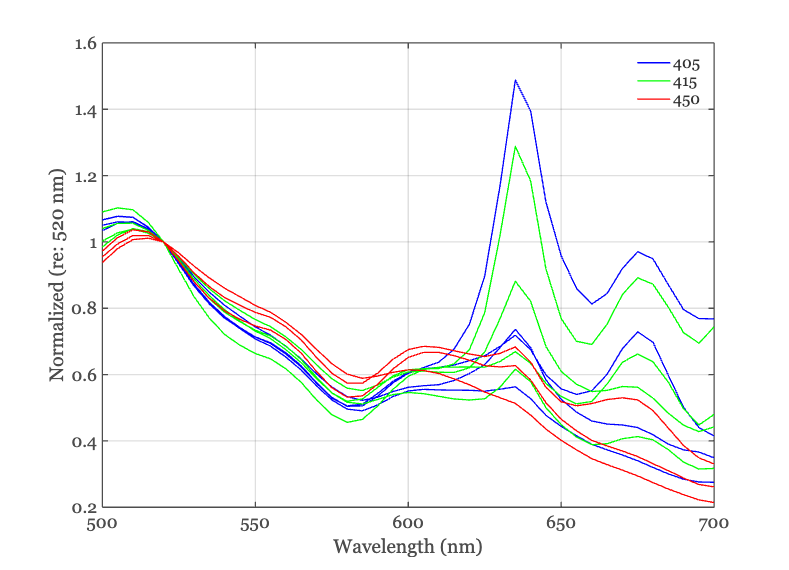

tongueFiles450 = ieTableGet(T,'ewave',450,'substrate','tongue','elevel',870,'return','files');

data = oeReadFiles(tongueFiles450,'waves',waves,'normalized wave',nWave);

% ieFigure;
hold on;
for ii= 1:numel(tongueFiles450)
    % plot(waves,data(:,ii),symbols{ii}); hold on; 
    hC = plot(waves,data(:,ii),'r-'); hold on; 
    set(gca,'yscale',yScale);
end
grid on;
xlabel('Wavelength (nm)')
if isempty(nWave), ylabel('Energy (watts/sr/nm/m^2)');
else, ylabel(sprintf('Normalized (re: %d nm)',nWave));
end
% title('Lip (450 ex)');
% legend({'J','Z','B','D'});
legend([hA,hB,hC],{'405','415','450'});
exportgraphics(gcf,'CompareLights-tongue.png','Resolution',150);